2.3

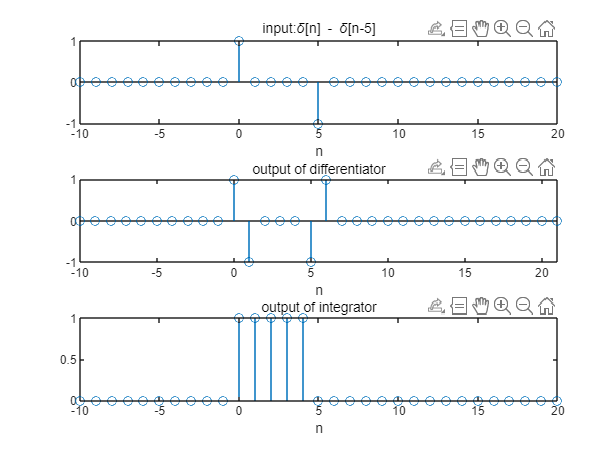


n = -10:20;
n2 = -10:21;
x1 = ((n-0)==0) - ((n-5)==0);
x2 = (n>=0) - (n>=11);
d1 = differentiator(x1,n);
d2 = differentiator(x2,n);
i1 = integrator(x1,n);
i2 = integrator(x2,n);
figure;
subplot(3,1,1);
stem(n,x1);
xlabel('n');
title('input:\delta[n] - \delta[n-5]');
subplot(3,1,2);
stem(n2,d1);
xlim([-10,21]);
xlabel('n');
title('output of differentiator');
subplot(3,1,3);
stem(n,i1);
xlabel('n');
title('output of integrator');

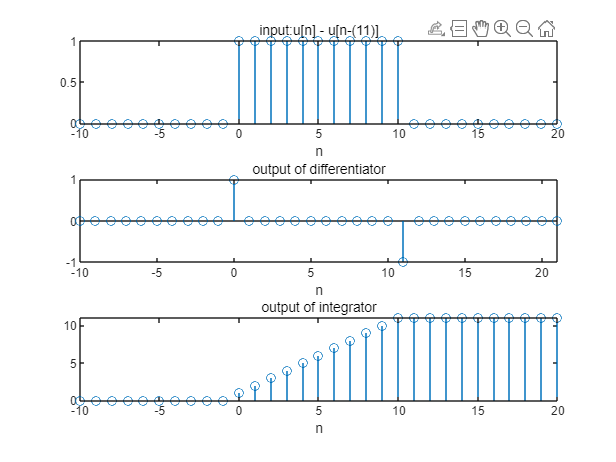



figure;
subplot(3,1,1);
stem(n,x2);
xlabel('n');
title('input:u[n] - u[n-(11)]');
subplot(3,1,2);
stem(n2,d2);
xlim([-10,21]);
xlabel('n');
title('output of differentiator');
subplot(3,1,3);
stem(n,i2);
xlabel('n');
title('output of integrator');

2.4

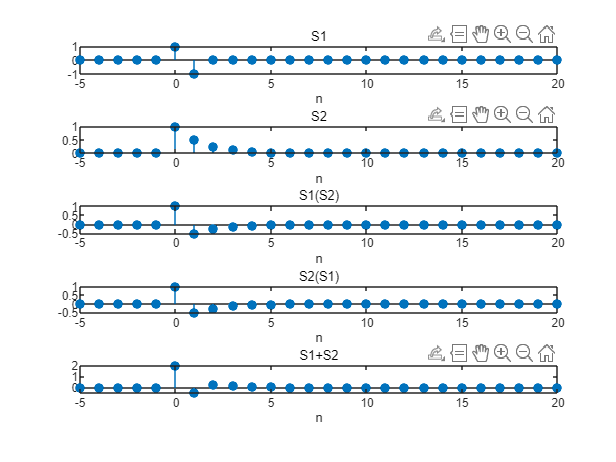

figure;
n = -5:20;
delta = ((n-0)==0);
y1 = filter_1(delta,n);
y1 = y1(1:length(n));
y2 = filter_2(delta,n);
y3 = filter_1(y2,n);
y3 = y3(1:length(n));
y4 = filter_2(y1,n);
y5 = y1+y2;
subplot(5,1,1);
stem(n,y1,'filled');
xlabel('n');
title('S1');
subplot(5,1,2);
stem(n,y2,'filled');
xlabel('n');
title('S2');
subplot(5,1,3);
stem(n,y3,'filled');
xlabel('n');
title('S1(S2)');
subplot(5,1,4);
stem(n,y4,'filled');
xlabel('n');
title('S2(S1)');
subplot(5,1,5);
stem(n,y5,'filled');
xlabel('n');
title('S1+S2');

2.5

y = audioread("music.au")

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


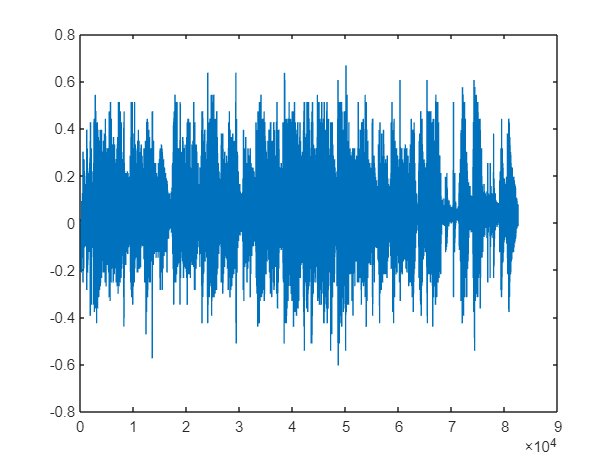

sound(y);
s1 = filter_1(y,y);
s2 = filter_2(y,y);
sound(s1);
sound(s2);
figure;
plot(y);

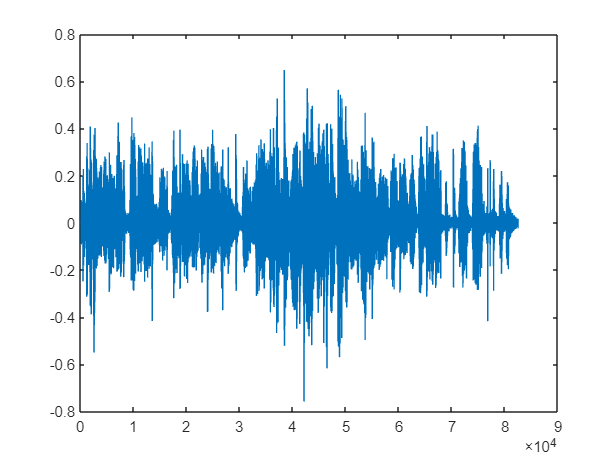

plot(s1);

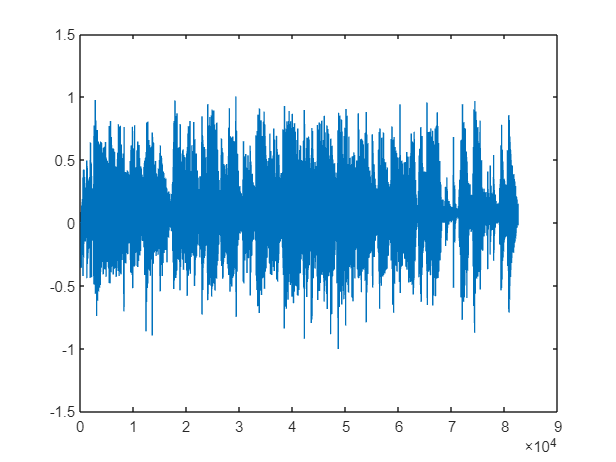

plot(s2);

2.6

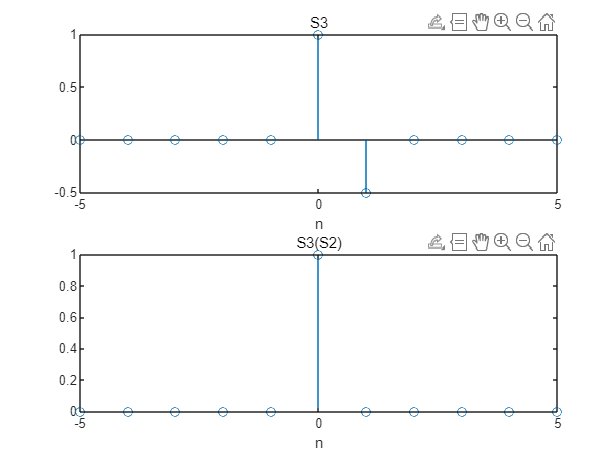

a = 1;
b = -0.5;
n = -5:5;
delta = ((n-0)==0);
y3 = filter_3(delta,n);
y3 = y3(1:length(n));
y2 = filter_2(delta,n); 
y32 = filter_3(y2,n);
y32 = y32(1:length(n));
figure;
subplot(2,1,1);
stem(n,y3);
xlabel('n');
title('S3');
subplot(2,1,2);
stem(n,y32);
xlabel('n');
title('S3(S2)');

2.7

n = -10:40;
s10 = sin(pi*n);
s1 = [zeros(1,5),s10,zeros(1,5)];
s20 = 0.5.^n;
s2 = [zeros(1,5),s20,zeros(1,5)];
s30 = randn(1,51);
s3 = [zeros(1,5),s30,zeros(1,5)];

bbox4

linear

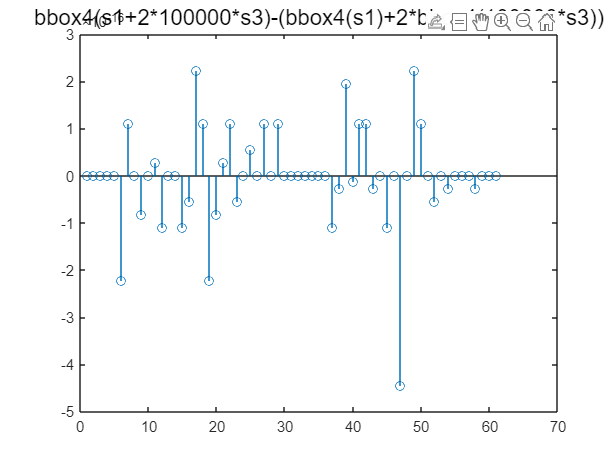

y1 = bbox4(s1);
y2 = bbox4(s2);
y3 = bbox4(s3);
z41 = bbox4(s1+2*s3);
z42 = y1+2*y3;
figure;
stem(z41-z42);
title('bbox4(s1+2*100000*s3)-(bbox4(s1)+2*bbox4(100000*s3))','FontSize',15);

bbox4

% s1_sf = [zeros(1,10),s10];
% z41_sf = bbox4(s1_sf)
% z42_sf = y1(1:length(y1)-5)
% z41_sf(6:length(y1))-z42_sf

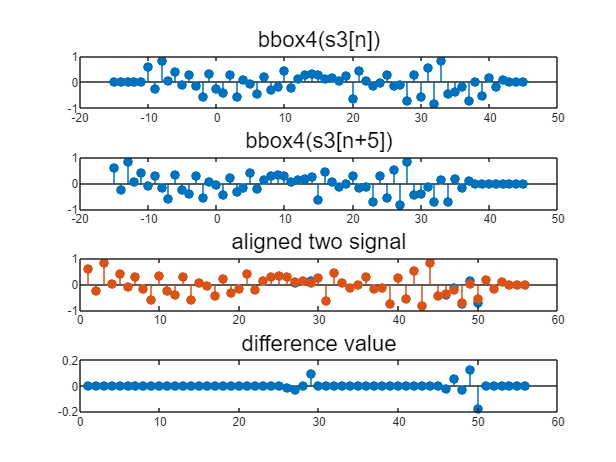

ans =     0.3000    0.1000         0


ans =          0    0.3000    0.1000


n2 = -15:45;
y3 = bbox4(s3);
s3_sf = [s30, zeros(1,10)];
z41_sf = bbox4(s3_sf);
z42_sf = y3(6:length(y2));
figure;
subplot(4,1,1)
stem(n2,y3,'filled');
title('bbox4(s3[n])','FontSize',15)
subplot(4,1,2)
stem(n2,z41_sf,'filled');
title('bbox4(s3[n+5])','FontSize',15)
subplot(4,1,3)
stem(z41_sf(1:length(y1)-5),'filled');
hold on
stem(z42_sf,'filled')
title('aligned two signal','FontSize',15)
subplot(4,1,4)
stem(z41_sf(1:length(y1)-5)-z42_sf,'filled');
title('difference value','FontSize',15)

bbox5

linear

y1 = bbox5(s1);
y2 = bbox5(s2);
y3 = bbox5(s3);
z41 = bbox5(s1+2*s2)

z41 = 1.0e+17 *

         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0002   -0.0005   -0.0010   -0.0020   -0.0035   -0.0062   -0.0104   -0.0172   -0.0277   -0.0437   -0.0679   -0.1037   -0.1558   -0.2301   -0.3339   -0.4752   -0.6616   -0.8973   -1.1776   -1.4787   -1.7398   -1.8329   -1.5124   -0.3341


z42 = y1+2*y2

z42 = 1.0e+17 *

         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0000   -0.0000   -0.0002   -0.0005   -0.0010   -0.0020   -0.0035   -0.0062   -0.0104   -0.0172   -0.0277   -0.0437   -0.0679   -0.1037   -0.1558   -0.2301   -0.3339   -0.4752   -0.6616   -0.8973   -1.1776   -1.4787   -1.7398   -1.8329   -1.5124   -0.3341


z41-z42

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


bbox5

% s1_sf = [s10,zeros(1,5)];
% z41_sf = bbox5(s1_sf)
% z42_sf = y1(6:length(y1))
% z41_sf-z42_sf

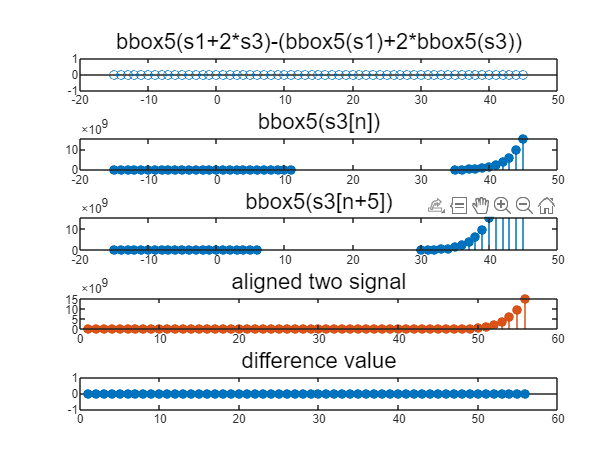

ans =          0    0.5500    1.1150    1.6155    2.7494


ans =          0         0    0.5500    1.1150    1.6155


figure;
y1 = bbox5(s1);
y2 = bbox5(s2);
y3 = bbox5(s3);
y3_scale = bbox5(100000*s3);
z41 = bbox5(s1+2*100000*s3);
z42 = y1+2*y3_scale;
subplot(5,1,1)
stem(n2,z41-z42);
title('bbox5(s1+2*s3)-(bbox5(s1)+2*bbox5(s3))','FontSize',15);
s3_sf = [s30,zeros(1,10)];
z41_sf = bbox5(s3_sf);
z42_sf = y3(6:length(y2));
n2 = -15:45;
subplot(5,1,2)
stem(n2,y3,'filled');
ylim([0 15.3*10^9]);
title('bbox5(s3[n])','FontSize',15)
subplot(5,1,3)
stem(n2,z41_sf,'filled');
ylim([0 15.3*10^9]);
title('bbox5(s3[n+5])','FontSize',15)
subplot(5,1,4)
stem(z41_sf(1:length(y1)-5),'filled');
hold on
stem(z42_sf,'filled')
title('aligned two signal','FontSize',15)
subplot(5,1,5)
stem(z41_sf(1:length(y1)-5)-z42_sf,'filled');
title('difference value','FontSize',15)

bbox6

non-linear

y1 = bbox6(s1);
y2 = bbox6(s2);
y3 = bbox6(s3);
z41 = bbox6(s1+2*s2)

z41 = 1.0e+06 *

         0         0         0         0         0    8.3886    2.0972    0.5243    6.4246    1.6067    0.4019    0.1006    0.0252    0.0063    0.0016    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


z42 = y1+2*y2

z42 = 1.0e+06 *

         0         0         0         0         0    4.1943    1.0486    0.2621    3.2133    0.8038    0.2012    0.0504    0.0127    0.0032    0.0008    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


z41-z42

ans = 1.0e+06 *

         0         0         0         0         0    4.1943    1.0486    0.2621    3.2113    0.8028    0.2007    0.0502    0.0125    0.0031    0.0008    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


bbox6

% s1_sf = [s10,zeros(1,5)];
% z41_sf = bbox6(s1_sf)
% z42_sf = y1(6:length(y1))
% z41_sf-z42_sf

% s3_sf = [s30,zeros(1,5)];
% z41_sf = bbox6(s3_sf)
% z42_sf = y3(6:length(y2))
% z41_sf-z42_sf

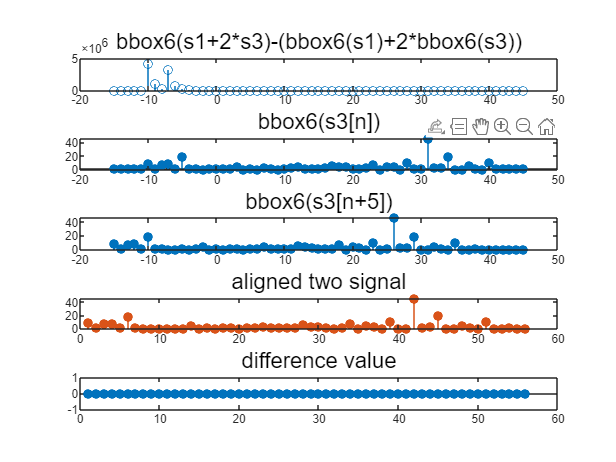

ans =      0     2     2     0     3


ans =      0     0     2     2     0     3


figure;
y1 = bbox6(s1);
y2 = bbox6(s2);
y3 = bbox6(s3);
z41 = bbox6(s1+2*s2);
z42 = y1+2*y2;
subplot(5,1,1)
stem(n2,z41-z42);
title('bbox6(s1+2*s3)-(bbox6(s1)+2*bbox6(s3))','FontSize',15);
s3_sf = [s30,zeros(1,10)];
z41_sf = bbox6(s3_sf);
z42_sf = y3(6:length(y2));
n2 = -15:45;
subplot(5,1,2)
stem(n2,y3,'filled');
title('bbox6(s3[n])','FontSize',15)
subplot(5,1,3)
stem(n2,z41_sf,'filled');
title('bbox6(s3[n+5])','FontSize',15)
subplot(5,1,4)
stem(z41_sf(1:length(y1)-5),'filled');
hold on
stem(z42_sf,'filled')
title('aligned two signal','FontSize',15)
subplot(5,1,5)
stem(z41_sf(1:length(y1)-5)-z42_sf,'filled');
title('difference value','FontSize',15)

2.8

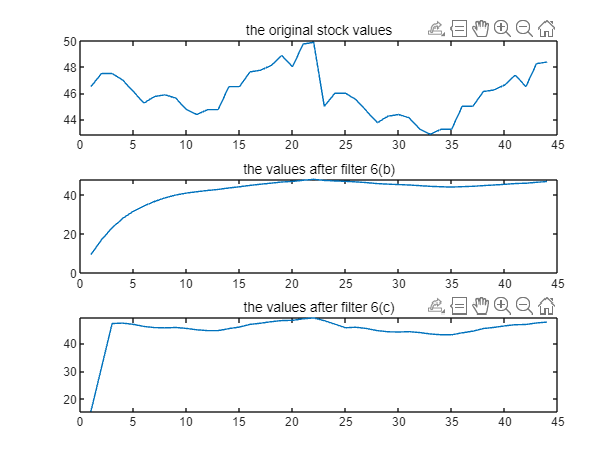

load stockrates.mat;
y4 = filter_4(rate,rate);
y5 = filter_5(rate,rate);
figure;
subplot(3,1,1);
plot(rate);
title('the original stock values');
subplot(3,1,2);
plot(y4);
title('the values after filter 6(b)');
subplot(3,1,3);
plot(y5);
title('the values after filter 6(c)');

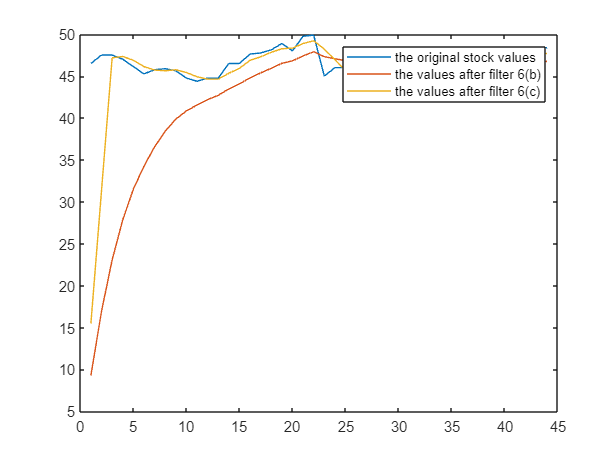

figure;
plot(rate);
hold on;
plot(y4);
hold on;
plot(y5);
legend('the original stock values','the values after filter 6(b)','the values after filter 6(c)')